# Demonstration of a PnP operation for a DGU Network

clear
close all
% USE MOSEK as solver (ADD to path)
addpath 'C:\Program Files\Mosek\9.3\toolbox\R2015aom'
addpath(genpath(cd));

- Initialize Network: Complete configuration of the network with all the electrical parameters is load from a text file

utils = utilityFunctions;
PnP = SimFunctionsPnP;
config = "DISTRIBUTED"; % distributed config, for plot function
filename = 'config_DGU_1.txt';
[nb_subsystems, Vin,R,L,C, Vmax, Vmin, Imax, Imin] = utils.importData(filename);

    {'subsystems'}    {'Vin'}    {'R     '}    {'L     '}    {'C    '}    {'Vmax'}    {'Vmin'}    {'Imax'}    {'Imin'}

    6.0000  100.0000    0.0030    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0015    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0017    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0016    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0015    0.0001    0.0001   52.0000   49.0000   10.0000         0
       NaN  100.0000    0.0016    0.0001    0.0001   52.0000   49.0000   10.0000         0



dguNet = DGU_network(nb_subsystems); % Instantiate a DGU NETWORK class

- Set references $V_r$ [V] to converge to and load current $I_l$ [A]

Vr = linspace(49.975, 50.1, nb_subsystems)% references

Vr =    49.9750   50.0000   50.0250   50.0500   50.0750   50.1000


Il = linspace(3.5, 5.5, nb_subsystems)

Il =     3.5000    3.9000    4.3000    4.7000    5.1000    5.5000


% set Electrical parameters and Dynamics for ALL the subsystems in the network
for i=1:nb_subsystems
    dguNet = dguNet.initElecParam(i,Vin(i), Vr(i), Il(i), R(i), C(i), L(i), ...
                                  Vmax(i), Vmin(i), Imax(i), Imin(i));
end

### A) For now consider only 5 active DGU out of 6

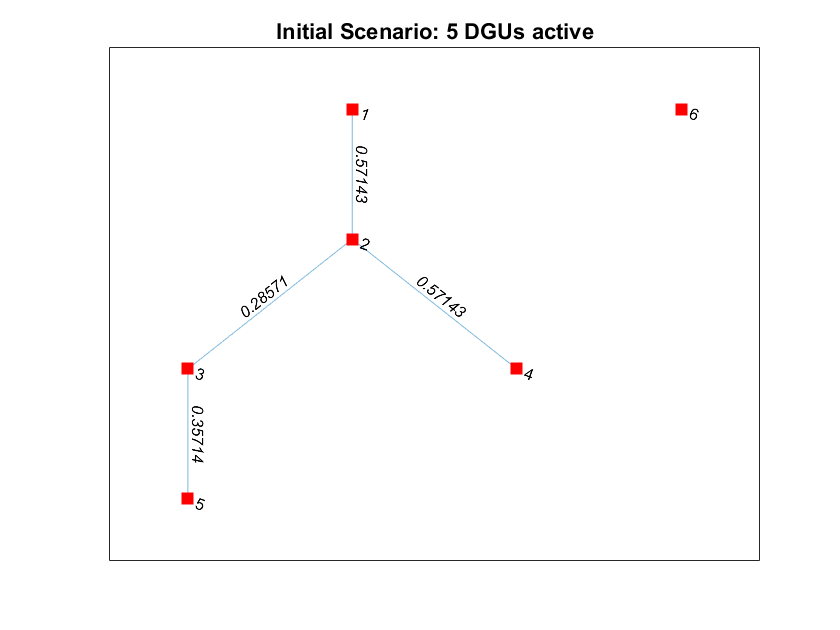

activeDGU_scen1 = 1:1:5; % Initially, 5 DGUs are active
Rij_mat = zeros(nb_subsystems);
Rij_mat(1,2) = 1.75; Rij_mat(2,3) = 3.5; Rij_mat(2,4) = 1.75; 
Rij_mat(3,5) = 2.8; 
Rij_mat = Rij_mat + tril(Rij_mat',1); % Non directed graph, symmetric matrix
dguNet = dguNet.setConnectionsGraph(Rij_mat); % set links between DGU
dguNet = dguNet.setActiveDGU(activeDGU_scen1); % define which DGUs are active
figure()
plot(dguNet.NetGraph, 'EdgeLabel', dguNet.NetGraph.Edges.Weight, 'Marker', 's', 'NodeColor','r', ...
      'MarkerSize', 7);
title("Initial Scenario: 5 DGUs active");

dguNet = dguNet.initDynamics(); % initialize dynamics

For passivity based MPC, constraints are not in $\Delta$ Formulation 

delta_config = false; % not in delta configuration
dguNet = dguNet.compute_Ref_Constraints(delta_config);
control_type = "MPC online";
[x0, Q_Ni, Ri] = utils.tuningParam(dguNet, delta_config)

x0 = 1×6 cell array
    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}    {2×1 double}


Q_Ni = 1×6 cell array
    {4×4 double}    {8×8 double}    {6×6 double}    {4×4 double}    {4×4 double}    {2×2 double}


Ri = 1×6 cell array
    {[1]}    {[1]}    {[1]}    {[1]}    {[1]}    {[1]}


- Use passivity to find the local passive feedback gains $K_i$ and $P_i$ s.t. $V_i(x_i) = x_i^T P_i x_i$

dguNet = PnP.setPassiveControllers(dguNet);

ans = "K1"

   -0.6387   -0.1384



ans = "P1"

   49.8098    3.2712
    3.2712    1.1312



ans = "K2"

   -0.0103   -0.1017



ans = "P2"

    2.9528    0.5446
    0.5446    4.1612



ans = "K3"

   -0.4957   -0.1504



ans = "P3"

   24.7525    2.1795
    2.1795    1.0425



ans = "K4"

   -0.1136   -0.1017



ans = "P4"

   11.4766    1.4834
    1.4834    1.8648



ans = "K5"

   -0.6108   -0.1390



ans = "P5"

   67.5107    4.6917
    4.6917    1.6810



- Use the tracking MPC with reconfigurable terminal ingredients  to converge to reference from the initial state

simStart = 1;
length_sim = 25;
[X, U] = PnP.mpc_DGU_tracking(@trackingMPC_reconf, x0, length_sim, dguNet, Q_Ni, Ri);

--INFO: Using controller trackingMPC_reconf -- 
 

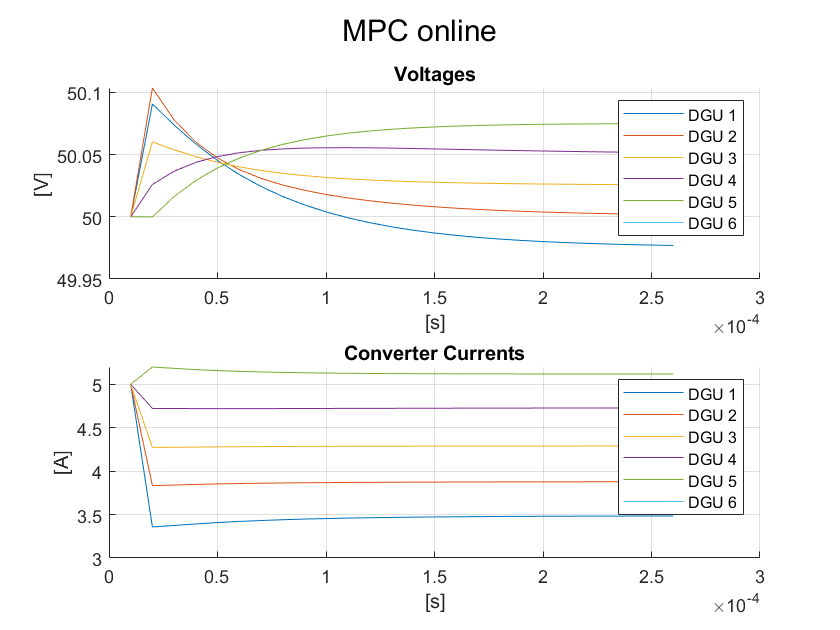

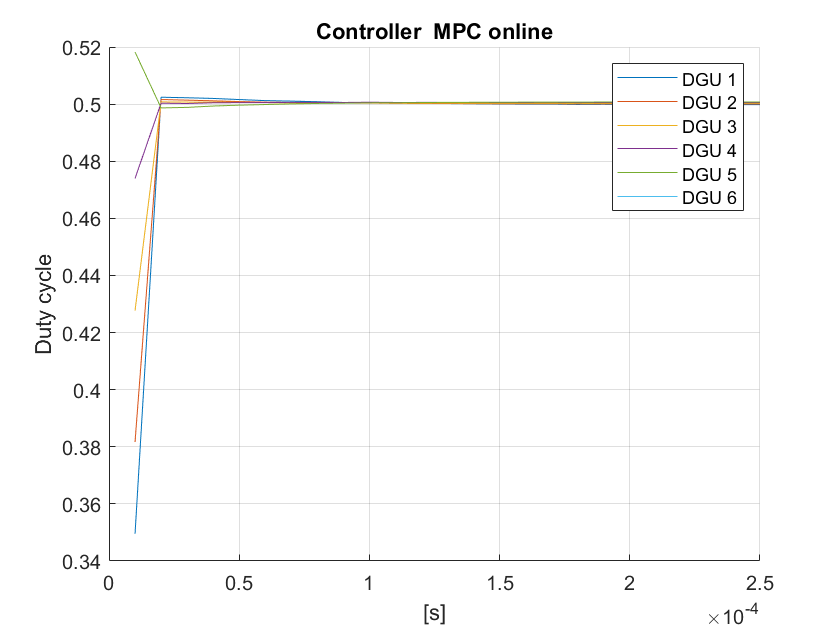

dguNet.plot_DGU_system(X,U, config, control_type, dguNet, simStart, 1:6); % plot results

clear X U
[X, U] = PnP.mpc_DGU_tracking(@trackingMPC_reconf_admm, x0, length_sim, dguNet, Q_Ni, Ri);

--INFO: Using controller trackingMPC_reconf_admm -- 
 Time elapsed to converge 4.786076e-01 and number of iterations 32 
Time elapsed to converge 3.674118e-01 and number of iterations 26 
Time elapsed to converge 3.702220e-01 and number of iterations 26 
Time elapsed to converge 4.910200e-01 and number of iterations 26 
Time elapsed to converge 4.321848e-01 and number of iterations 26 
Time elapsed to converge 3.602209e-01 and number of iterations 26 
Time elapsed to converge 3.520943e-01 and number of iterations 26 
Time elapsed to converge 4.007211e-01 and number of iterations 26 
Time elapsed to converge 3.777808e-01 and number of iterations 26 
Time elapsed to converge 3.424520e-01 and number of iterations 26 
Time elapsed to converge 3.456782e-01 and number of iterations 26 
Time elapsed to converge 3.382145e-01 and number of iterations 26 
Time elapsed to converge 3.534307e-01 and number of iterations 26 
Time elapsed to converge 3.545257e-01 and number of iterations 26 
Time ela

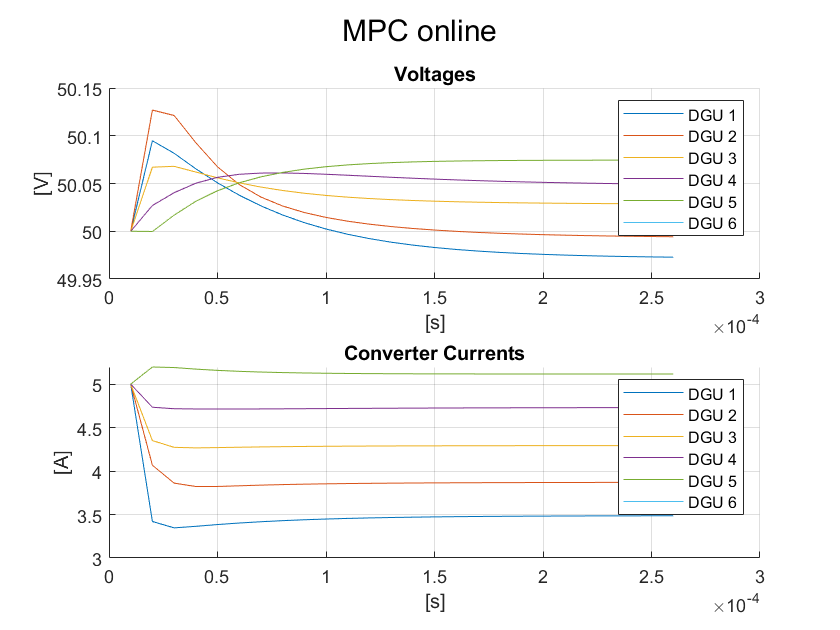

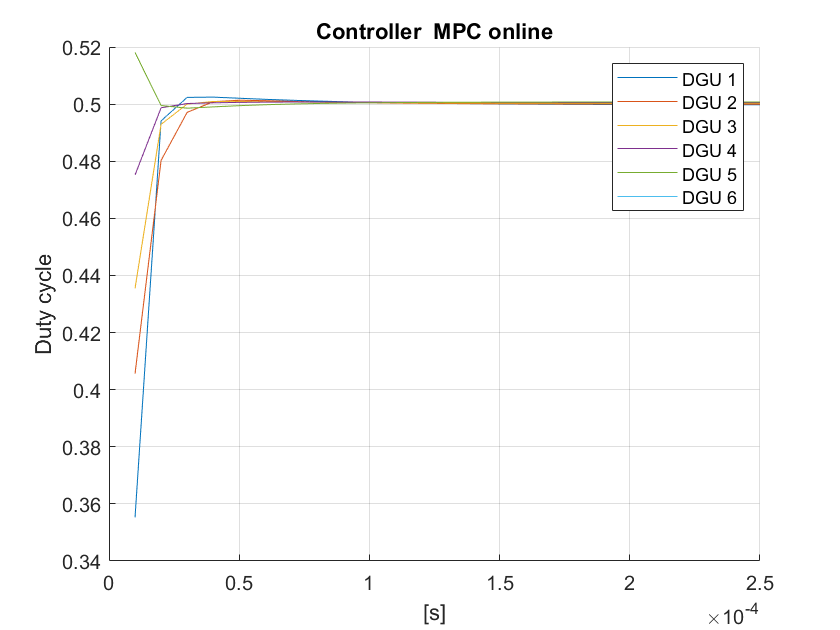

dguNet.plot_DGU_system(X,U, config, control_type, dguNet, simStart, 1:6); % plot results

### B) Scenario 2: Connect DGU 6 to DGU 3

Set all DGUs to be active. DGU 6 is now active but is not connected yet to the network

simStart2 = simStart + length_sim;
dguPos = 6;
activeDGU_scen2 = 1:1:6; % Now all the 6 DGUs are active
dguNet = dguNet.setActiveDGU(activeDGU_scen2);
dguNet2 = dguNet; % dguNet copy, with 6 active DGU but before connection

Create connection from DGU 6 to DGU 3. For this purpose, a new instance of the network class is created with the modified structure e.g. different Laplacian matrix and $A_{Ni}$ 

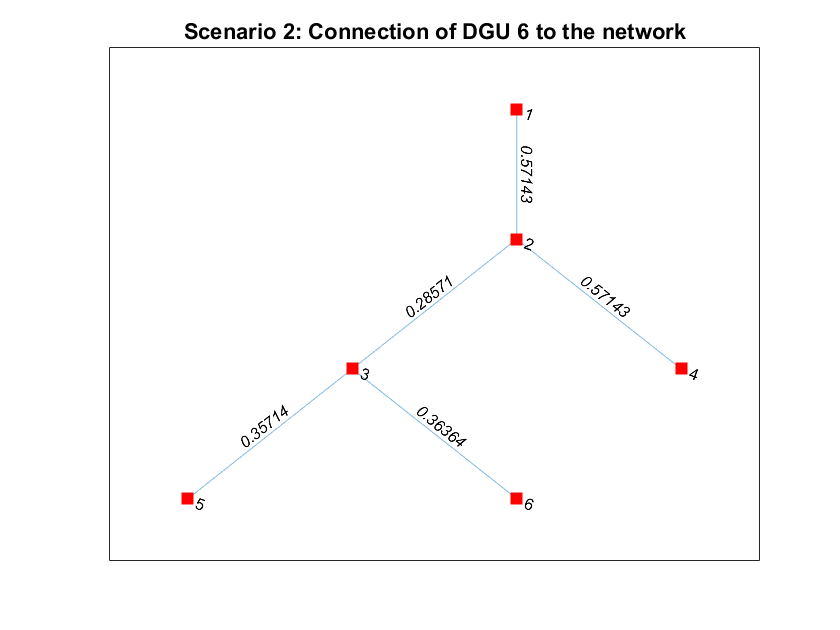

Rij_mat(3,dguPos) = 2.75; Rij_mat(dguPos,3) = Rij_mat(3,dguPos);  % New link
dguNet2 = dguNet2.setConnectionsGraph(Rij_mat);
dguNet2 = dguNet2.initDynamics(); % recompute Dynamics (changed with integration of DGU 6)
plot(dguNet2.NetGraph, 'EdgeLabel', dguNet2.NetGraph.Edges.Weight, 'Marker', 's', 'NodeColor','r', ...
      'MarkerSize', 7);
title('Scenario 2: Connection of DGU 6 to the network')

dguNet2 = dguNet2.compute_Ref_Constraints(delta_config);

- **Redesign Phase**: Compute new $K_i$ and $P_i$ of neighbors set of DGU 6 (including DGU 6 itself)

dguNet2 = PnP.redesignPhase(dguNet2, dguNet2.NetGraph,dguPos, "add");

ans = "New passive controller gain of system 3"

   -0.4650   -0.1511



ans = "P3"

   15.8061    1.3570
    1.3570    0.6736



ans = "New passive controller gain of system 6"

   -0.5574   -0.1421



ans = "P6"

   53.5936    4.1295
    4.1295    1.6485



Re-define Q_Ni since neighbors of DGU 3 and 6 changed. Initial values for the 5 first DGUs taken from previous simulation end. 

[x0, Q_Ni, Ri, Qi] = utils.tuningParam(dguNet2, delta_config); 
for i = activeDGU_scen1
    x0{i} = X{end}(:,i);   %
end
disp('x0'); celldisp(x0);

x0
 
x0{1} =
 
   49.9728
   -0.0142

 
 
x0{2} =
 
   49.9943
   -0.0300

 
 
x0{3} =
 
   50.0286
   -0.0070

 
 
x0{4} =
 
   50.0492
    0.0301

 
 
x0{5} =
 
   50.0745
    0.0164

 
 
x0{6} =
 
   50.0000
   -0.5000

 


- **Transition Phase**: Compute steady-state value to reach to allow the plug-in of DGU 6 (*PnP permitted). *Drive the system (the 5 initial DGU's + the 6th DGU before connection) to this steady state.

ADMM = false;
[X2_trans,U2_trans,lenSim, xs,us,alpha]= PnP.transitionPhase(x0, dguNet, dguNet2, Qi, Ri, 'reference', ADMM)

Not using ADMM !
Feasible steady-state found
Regulation to steady-state: iteration 1 
Regulation to steady-state: iteration 2 
Regulation to steady-state: iteration 3 
Regulation to steady-state: iteration 4 
Regulation to steady-state: iteration 5 
Regulation to steady-state: iteration 6 
Regulation to steady-state: iteration 7 


X2_trans = 1×8 cell array
    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}


U2_trans = 1×7 cell array
    {[0.4998 0.5013 0.4987 0.5005 0.5015 0.5512]}    {[0.4997 0.4999 0.5003 0.5005 0.5007 0.4998]}    {[0.4997 0.5000 0.5003 0.5005 0.5007 0.4995]}    {[0.4997 0.5000 0.5003 0.5005 0.5008 0.4996]}    {[0.4997 0.5000 0.5002 0.5005 0.5008 0.4997]}    {[0.4997 0.5000 0.5002 0.5005 0.5008 0.4997]}    {[0.4997 0.5000 0.5002 0.5005 0.5008 0.4998]}


lenSim = 8

xs =    49.9766   50.0014   50.0155   50.0516   50.0799   50.1000
   -0.0142   -0.0185   -0.0190    0.0287    0.0230         0


us =     0.4998    0.5000    0.5002    0.5005    0.5008    0.5010


alpha =   -11.2233
   -3.5990
   -8.8849
  -13.2898
   -9.1900
   -7.9445


clear X2_trans U2_trans lenSim xs us alpha
ADMM = true;
[X2_trans,U2_trans,lenSim, xs,us,alpha]= PnP.transitionPhase(x0, dguNet, dguNet2, Qi, Ri, 'reference', ADMM)

Using ADMM !
Iteration 1,  Time elapsed for each iteration 1.348470e-02 
Iteration 2,  Time elapsed for each iteration 2.696680e-02 
Iteration 3,  Time elapsed for each iteration 3.903960e-02 
Iteration 4,  Time elapsed for each iteration 5.248490e-02 
Iteration 5,  Time elapsed for each iteration 6.620690e-02 
Iteration 6,  Time elapsed for each iteration 8.244350e-02 
Iteration 7,  Time elapsed for each iteration 9.501960e-02 
Iteration 8,  Time elapsed for each iteration 1.104370e-01 
Iteration 9,  Time elapsed for each iteration 1.232020e-01 
Iteration 10,  Time elapsed for each iteration 1.357045e-01 
Iteration 11,  Time elapsed for each iteration 1.490988e-01 
Iteration 12,  Time elapsed for each iteration 1.655495e-01 
Iteration 13,  Time elapsed for each iteration 1.831878e-01 
Iteration 14,  Time elapsed for each iteration 2.039934e-01 
Iteration 15,  Time elapsed for each iteration 2.228336e-01 
Iteration 16,  Time elapsed for each iteration 2.370579e-01 
Iteration 17,  Time 

X2_trans = 1×8 cell array
    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}


U2_trans = 1×7 cell array
    {[0.4997 0.5008 0.4977 0.5003 0.5009 0.5478]}    {[0.4997 0.5000 0.5002 0.5005 0.5008 0.5030]}    {[0.4997 0.5000 0.5003 0.5005 0.5008 0.4997]}    {[0.4997 0.5000 0.5003 0.5005 0.5008 0.4995]}    {[0.4997 0.5000 0.5002 0.5005 0.5008 0.4996]}    {[0.4997 0.5000 0.5002 0.5005 0.5008 0.4997]}    {[0.4997 0.5000 0.5002 0.5005 0.5008 0.4998]}


lenSim = 8

xs =    49.9735   50.0009   50.0215   50.0485   50.0762   50.1000
   -0.0148   -0.0217   -0.0355    0.0284    0.0172         0


us =     0.4997    0.5000    0.5002    0.5005    0.5008    0.5010


alpha =    -6.4084
   -1.0255
   -6.3669
   -6.4685
   -2.3756
   -0.9574


Initial states for reference MPC tracking are the states from the end of the transition phase (i.e. corresponding to steady state where P&P permitted):

for i = activeDGU_scen2
    x0{i} = X2_trans{end}(:,i);   
end
lenSim2 = 25;
annot2plot.array = dguNet2.Ts*[simStart2,simStart2+lenSim];
annot2plot.text = {'Start Transition Phase', 'End Transition Phase'};
[X2, U2] = PnP.mpc_DGU_tracking(@trackingMPC_reconf_admm, x0, lenSim2, dguNet2, Q_Ni, Ri);

--INFO: Using controller trackingMPC_reconf_admm -- 
 Time elapsed to converge 5.076997e-01 and number of iterations 32 
Time elapsed to converge 5.185825e-01 and number of iterations 32 
Time elapsed to converge 5.210045e-01 and number of iterations 32 
Time elapsed to converge 4.999599e-01 and number of iterations 32 
Time elapsed to converge 5.058306e-01 and number of iterations 32 
Time elapsed to converge 5.821658e-01 and number of iterations 32 
Time elapsed to converge 4.909046e-01 and number of iterations 32 
Time elapsed to converge 5.117251e-01 and number of iterations 32 
Time elapsed to converge 5.257372e-01 and number of iterations 32 
Time elapsed to converge 5.026349e-01 and number of iterations 32 
Time elapsed to converge 5.055043e-01 and number of iterations 32 
Time elapsed to converge 5.192996e-01 and number of iterations 32 
Time elapsed to converge 5.613124e-01 and number of iterations 32 
Time elapsed to converge 5.024152e-01 and number of iterations 32 
Time ela

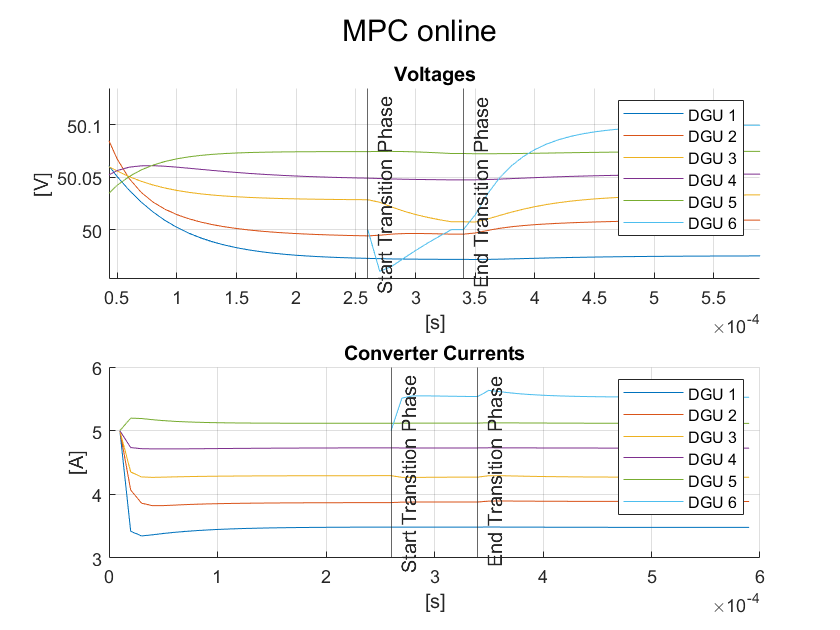

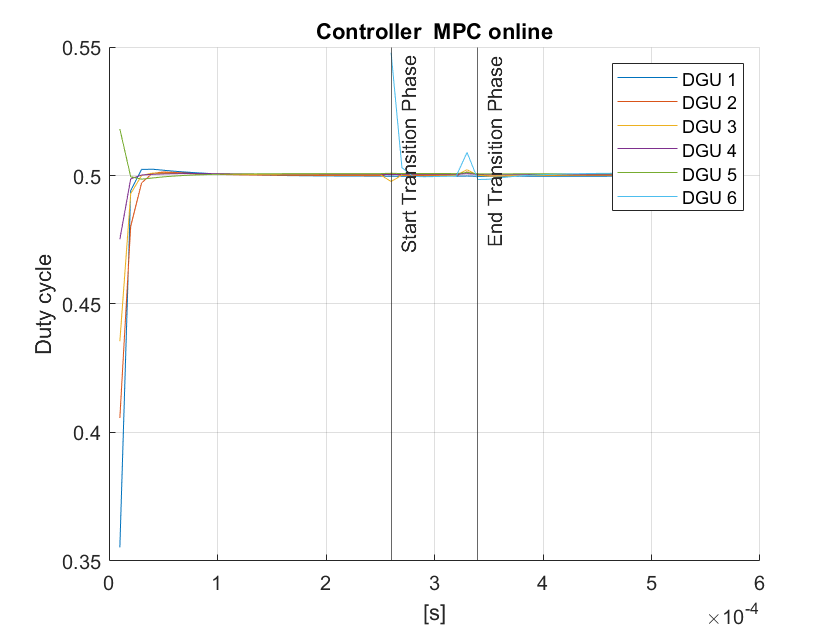

dguNet2.plot_DGU_system([X(1:end-1),X2_trans,X2],[U, U2_trans, U2], config, control_type, dguNet2, simStart, activeDGU_scen2, annot2plot); % plot results

#### C) 3rd Scenario: Plug out DGU 4

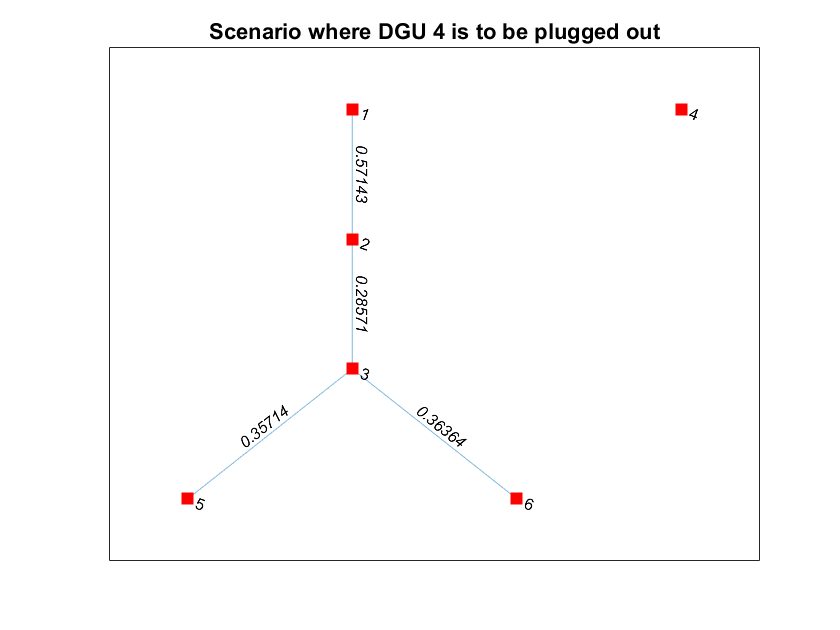

activeDGU_scen3 = [1 2 3 5 6]; % remove DGU 4 from active DGU list
dguNet3 = dguNet2; % copy the previous instance with 6 DGUs and create new instance for this scenario
dguNet3 = dguNet3.setActiveDGU(activeDGU_scen3);
dguDelete = 4;
Rij_mat(dguDelete,:) = 0; Rij_mat(:,dguDelete) = 0;
dguNet3 = dguNet3.setConnectionsGraph(Rij_mat);
dguNet3 = dguNet3.initDynamics();
plot(dguNet3.NetGraph, 'EdgeLabel', dguNet3.NetGraph.Edges.Weight, 'Marker', 's', 'NodeColor','r', ...
      'MarkerSize', 7);
title('Scenario where DGU 4 is to be plugged out')

dguNet3 = dguNet3.compute_Ref_Constraints(delta_config);

- **Redesign Phase**: Compute new $K_i$ and $P_i$ of neighbors set of DGU 4

dguNet3 = PnP.redesignPhase(dguNet3, dguNet2.NetGraph, dguDelete, "delete");

ans = "New passive controller gain of system 2"

   -0.0361   -0.1044



ans = "P2"

    4.1053    0.7316
    0.7316    2.5140



- **Transition Phase**: Take as initial state the end of simulation of scenario 2

% call again since dimension of Q_Ni change when adding/removing DGU
[~, Q_Ni, Ri, Qi] = utils.tuningParam(dguNet3, delta_config);
for i = activeDGU_scen2
    x0{i} = X2{end}(:,i);   
end
disp('x0'); celldisp(x0);

x0
 
x0{1} =
 
   49.9752
   -0.0193

 
 
x0{2} =
 
   50.0092
   -0.0123

 
 
x0{3} =
 
   50.0333
   -0.0318

 
 
x0{4} =
 
   50.0531
    0.0253

 
 
x0{5} =
 
   50.0747
    0.0149

 
 
x0{6} =
 
   50.0996
    0.0244

 


Define new references, to see the effect of the objective function of the optimization problem:

dguNet3.Vr = linspace(49.90, 50.4, nb_subsystems);% references
dguNet3.Il = linspace(2.5, 7.5, nb_subsystems);
dguNet3 = dguNet3.compute_Ref_Constraints(delta_config);

$f^i (x_s^i , u_s^i, x^i) = {||x_s^i - x_0^i ||}^2$ will keep the steady state as close as possible to the current state: for quick P&P operation

ADMM = true;
[X3_trans_,U3_trans_,lenTrans_, xs_,us_,alpha_]= PnP.transitionPhase(x0, dguNet2, dguNet3, Qi, Ri, 'current state', ADMM)

Using ADMM !
Iteration 1,  Time elapsed for each iteration 1.750660e-02 
Iteration 2,  Time elapsed for each iteration 2.983860e-02 
Iteration 3,  Time elapsed for each iteration 4.139300e-02 
Iteration 4,  Time elapsed for each iteration 5.215610e-02 
Iteration 5,  Time elapsed for each iteration 6.343950e-02 
Iteration 6,  Time elapsed for each iteration 7.449850e-02 
Iteration 7,  Time elapsed for each iteration 8.579820e-02 
Iteration 8,  Time elapsed for each iteration 9.731710e-02 
Iteration 9,  Time elapsed for each iteration 1.083609e-01 
Iteration 10,  Time elapsed for each iteration 1.195061e-01 
Iteration 11,  Time elapsed for each iteration 1.303060e-01 
Iteration 12,  Time elapsed for each iteration 1.445733e-01 
Iteration 13,  Time elapsed for each iteration 1.565374e-01 
Iteration 14,  Time elapsed for each iteration 1.682981e-01 
Iteration 15,  Time elapsed for each iteration 1.803432e-01 
Iteration 16,  Time elapsed for each iteration 1.909850e-01 
Iteration 17,  Time 

X3_trans_ = 1×1 cell array
    {2×6 double}


U3_trans_ = 1×1 cell array
    {[0.4998 0.5001 0.5004 0.5005 0.5007 0.5010]}


lenTrans_ = 1

xs_ =    49.9752   50.0089   50.0354   50.0529   50.0742   50.0991
   -0.0194   -0.0125   -0.0330    0.0256    0.0145    0.0240


us_ =     0.4998    0.5001    0.5004    0.5005    0.5007    0.5010


alpha_ =    -6.3052
   -2.7300
   -6.3480
         0
   -2.3759
   -2.6272


$f^i (x_s^i , u_s^i, x^i) = {||x_s^i - x_r^i ||}^2$ will keep the steady state as close as possible from the references, with the goal of reducing modification to the desired system behaviour

[X3_trans,U3_trans,lenTrans, xs,us,alpha]= PnP.transitionPhase(x0, dguNet2, dguNet3, Qi, Ri, 'reference', ADMM)

Using ADMM !
Iteration 1,  Time elapsed for each iteration 1.250380e-02 
Iteration 2,  Time elapsed for each iteration 2.908500e-02 
Iteration 3,  Time elapsed for each iteration 4.302050e-02 
Iteration 4,  Time elapsed for each iteration 5.789200e-02 
Iteration 5,  Time elapsed for each iteration 7.183690e-02 
Iteration 6,  Time elapsed for each iteration 8.363750e-02 
Iteration 7,  Time elapsed for each iteration 1.018329e-01 
Iteration 8,  Time elapsed for each iteration 1.181811e-01 
Iteration 9,  Time elapsed for each iteration 1.441225e-01 
Iteration 10,  Time elapsed for each iteration 1.561242e-01 
Iteration 11,  Time elapsed for each iteration 1.675647e-01 
Iteration 12,  Time elapsed for each iteration 1.832575e-01 
Iteration 13,  Time elapsed for each iteration 1.979620e-01 
Iteration 14,  Time elapsed for each iteration 2.134300e-01 
Iteration 15,  Time elapsed for each iteration 2.337649e-01 
Iteration 16,  Time elapsed for each iteration 2.483636e-01 
Iteration 17,  Time 

X3_trans = 1×14 cell array
    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}    {2×6 double}


U3_trans = 1×13 cell array
    {[0.4947 0.5033 0.4928 0.5040 0.5116 0.5171]}    {[0.4995 0.5003 0.4997 0.5007 0.5013 0.5017]}    {[0.4997 0.5001 0.5001 0.5005 0.5007 0.5009]}    {[0.4997 0.5002 0.5000 0.5005 0.5008 0.5011]}    {[0.4996 0.5002 0.4999 0.5006 0.5010 0.5014]}    {[0.4996 0.5002 0.4999 0.5007 0.5011 0.5016]}    {[0.4995 0.5002 0.4999 0.5007 0.5013 0.5018]}    {[0.4995 0.5002 0.4999 0.5008 0.5014 0.5020]}    {[0.4994 0.5002 0.5000 0.5008 0.5015 0.5022]}    {[0.4994 0.5002 0.5000 0.5009 0.5016 0.5023]}    {[0.4994 0.5002 0.5001 0.5009 0.5017 0.5025]}    {[0.4993 0.5002 0.5001 0.5009 0.5018 0.5026]}    {[0.4993 0.5002 0.5002 0.5009 0.5018 0.5027]}


lenTrans = 14

xs =    49.8969   50.0065   50.0984   50.1893   50.2994   50.3994
   -0.0575    0.0230   -0.1529    0.0185    0.0723    0.1100


us =     0.4990    0.5001    0.5010    0.5019    0.5030    0.5040


alpha =    -6.2985
   -2.7202
   -6.3675
         0
   -2.2704
   -2.4451


If P&P permitted, simulate normal operation of the network after plug out of DGU 4:

for i = activeDGU_scen3
    x0{i} = X3_trans{end}(:,i);   
end
lenSim3 = 20;
[X3, U3] = PnP.mpc_DGU_tracking(@trackingMPC_reconf_admm, x0, lenSim3, dguNet3, Q_Ni, Ri);

--INFO: Using controller trackingMPC_reconf_admm -- 
 Time elapsed to converge 3.610823e-01 and number of iterations 26 
Time elapsed to converge 3.600397e-01 and number of iterations 26 
Time elapsed to converge 4.373737e-01 and number of iterations 26 
Time elapsed to converge 3.739919e-01 and number of iterations 26 
Time elapsed to converge 3.818300e-01 and number of iterations 26 
Time elapsed to converge 3.403983e-01 and number of iterations 26 
Time elapsed to converge 4.655910e-01 and number of iterations 26 
Time elapsed to converge 4.027634e-01 and number of iterations 26 
Time elapsed to converge 3.381014e-01 and number of iterations 26 
Time elapsed to converge 3.432524e-01 and number of iterations 26 
Time elapsed to converge 4.370783e-01 and number of iterations 26 
Time elapsed to converge 3.486273e-01 and number of iterations 26 
Time elapsed to converge 3.400741e-01 and number of iterations 26 
Time elapsed to converge 3.424776e-01 and number of iterations 26 
Time ela

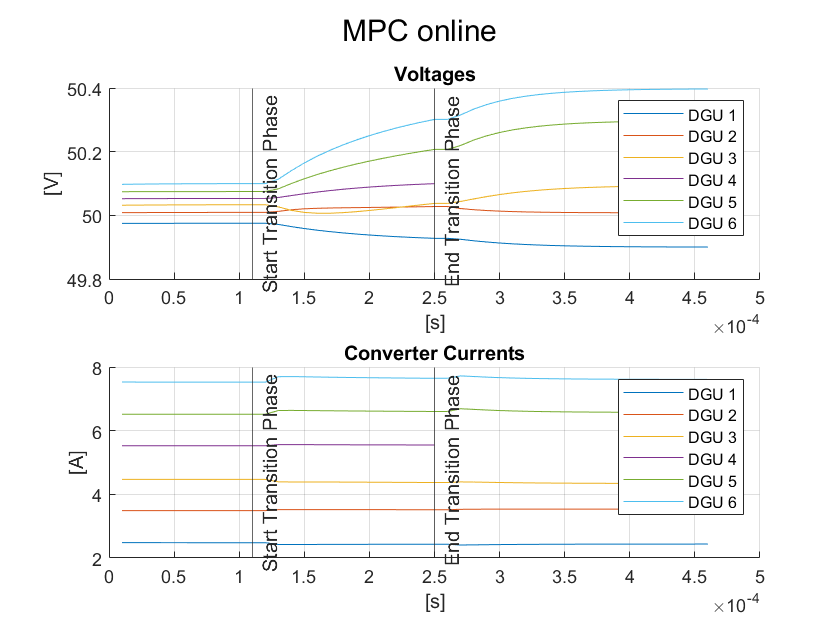

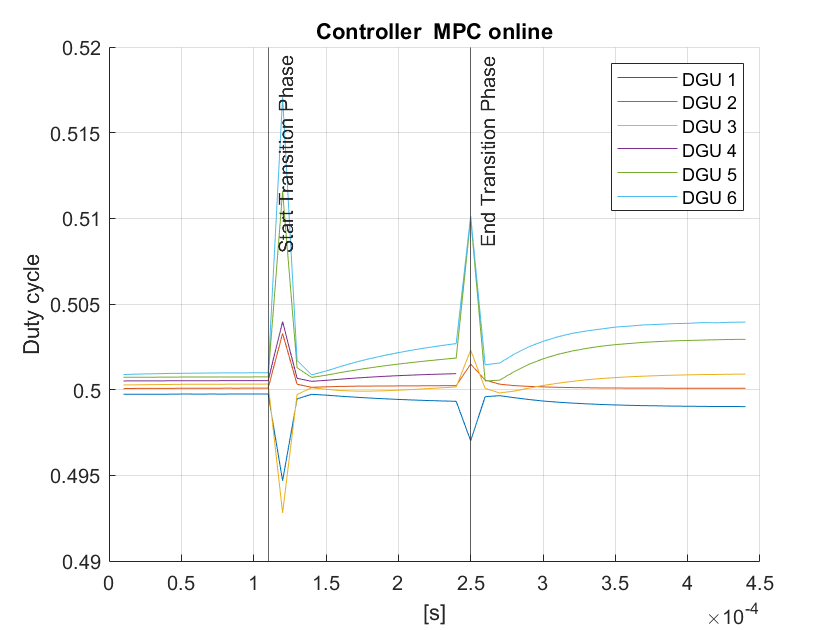

annot2plot.array = dguNet3.Ts*[11,11+lenTrans];
annot2plot.text = {'Start Transition Phase', 'End Transition Phase'};
% plot the last 11 points from the previous phase
dguNet3.plot_DGU_system([X2(end-10:end), X3_trans, X3],[U2(end-10:end), U3_trans, U3], config, ...
                control_type, dguNet3, simStart, activeDGU_scen2, annot2plot); % plot results